clear

fs = 2^13;
T = 0.5;

Part a

piano.harmonics = [0.5 0];
piano.envelope = @(t) min(40*t,1).*exp(-4*t);

% fplot(piano.envelope, [0 T])

Part b

mary2
w_song = [];
for i=1:(size(script,2))
    w_song = [w_song tone2(fs,script(i),piano)];
end
happy
for i=1:(size(script,2))
    w_song = [w_song tone2(fs,script(i),piano)];
end

Part c

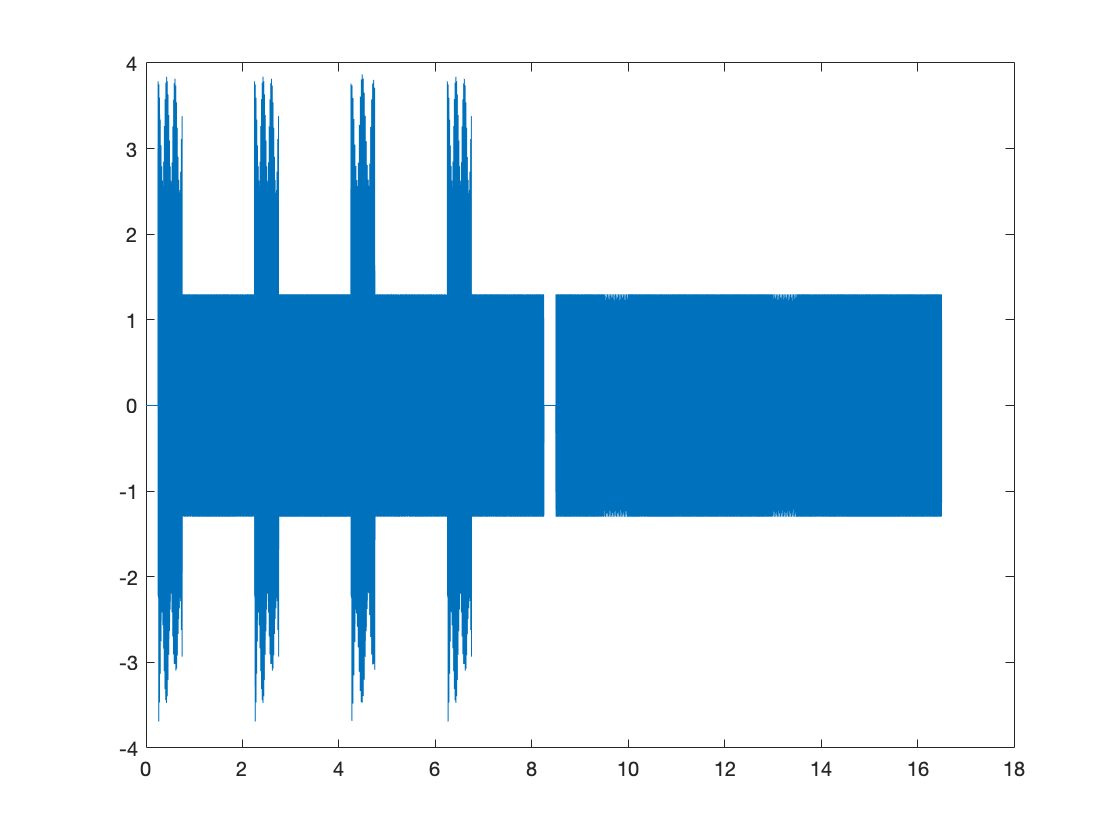

t = (1:length(w_song))/fs;

plot(t,w_song)

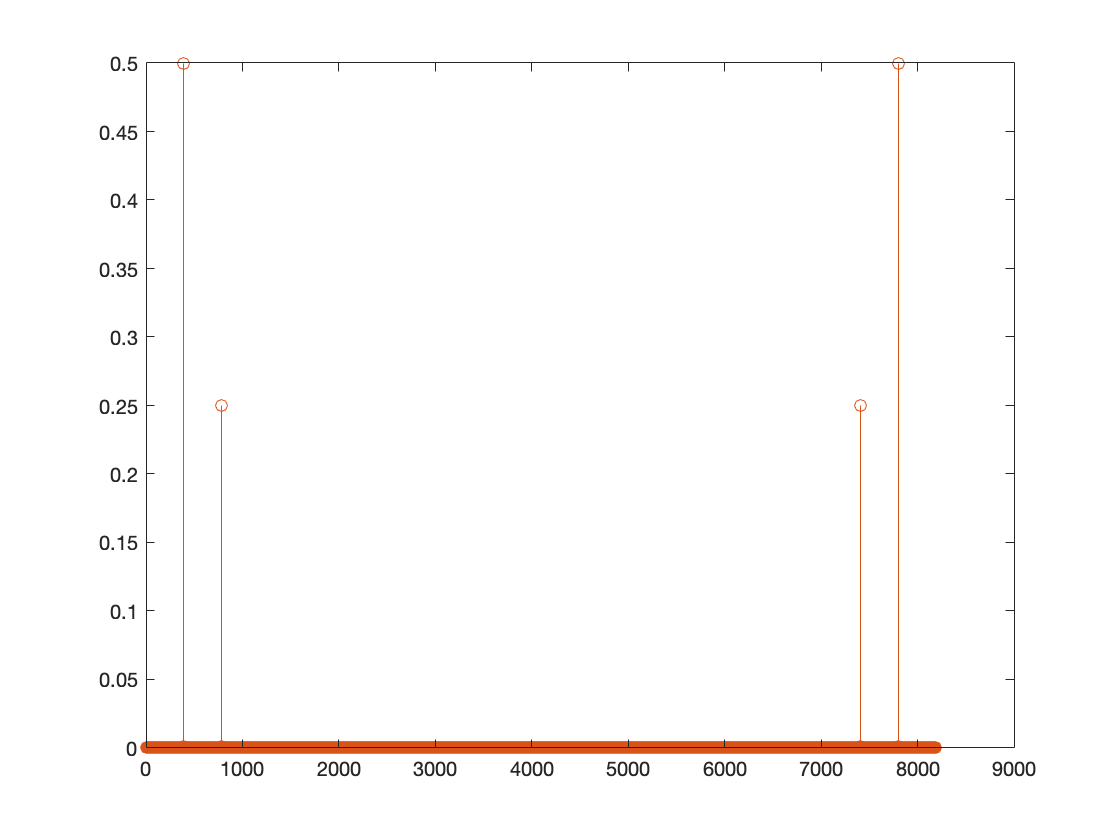


sound(w_song,fs)
tic

t_start = 0;
w_new = [];
for  i = 1:length(script)
    T = script(i).duration;
    
    w = w_song((t>t_start) & (t<=t_start+T));
    
    f = 0:1/T:fs-1/T;
    W = fft(w/length(w));
    
    stem(f,abs(W))
    hold on
    
    W((f>880) & (f<fs-880)) = 0;
    w_new = [w_new ifft(W*length(W))];
    
    stem(f,abs(W))
    hold off
    
    pause(0.01)
    
    t_start = t_start+T;
    
    while toc<t_start
    end

end


sound(w_new,fs)